syms x
a=-pi; 
b=pi; 
I=[a b];
l=(b-a)/2; 
y = exp(x);

a0 = vpa((1/l)*int(y,x,a,b),3); 
i = 25;
sum=0;
for n=1:i
an = (1/l)*int(y*cos((n*pi*x)/l),x,I); 
bn = (1/l)*int(y*sin((n*pi*x)/l),x,I); 
sum = sum + an*cos((n*pi*x)/l) + bn*sin((n*pi*x)/l);
end
F=vpa((a0/2)+sum,3) 

$$F = 1.47\,\cos\left(2.0\,x\right)+0.432\,\cos\left(4.0\,x\right)+0.113\,\cos\left(8.0\,x\right)+0.0286\,\cos\left(16.0\,x\right)-0.0254\,\cos\left(17.0\,x\right)-0.0897\,\cos\left(9.0\,x\right)+0.0226\,\cos\left(18.0\,x\right)-0.0203\,\cos\left(19.0\,x\right)-2.94\,\sin\left(2.0\,x\right)-1.73\,\sin\left(4.0\,x\right)-0.905\,\sin\left(8.0\,x\right)-0.458\,\sin\left(16.0\,x\right)-0.283\,\cos\left(5.0\,x\right)+0.0728\,\cos\left(10.0\,x\right)+0.0183\,\cos\left(20.0\,x\right)+0.431\,\sin\left(17.0\,x\right)-0.0166\,\cos\left(21.0\,x\right)+0.807\,\sin\left(9.0\,x\right)-0.407\,\sin\left(18.0\,x\right)-0.0603\,\cos\left(11.0\,x\right)+0.0152\,\cos\left(22.0\,x\right)+0.386\,\sin\left(19.0\,x\right)-0.0139\,\cos\left(23.0\,x\right)+1.41\,\sin\left(5.0\,x\right)-0.728\,\sin\left(10.0\,x\right)-0.367\,\sin\left(20.0\,x\right)-0.735\,\cos\left(3.0\,x\right)+0.199\,\cos\left(6.0\,x\right)+0.0507\,\cos\left(12.0\,x\right)+0.0127\,\cos\left(24.0\,x\right)+0.349\,\sin\left(21.0\,x\right)-0.0117\,\cos\left(25.0\,x\right)+0.663\,\sin\left(11.0\,x\right)-0.333\,\sin\left(22.0\,x\right)-0.0432\,\cos\left(13.0\,x\right)+0.319\,\sin\left(23.0\,x\right)+2.21\,\sin\left(3.0\,x\right)-1.19\,\sin\left(6.0\,x\right)-0.608\,\sin\left(12.0\,x\right)-0.306\,\sin\left(24.0\,x\right)-0.147\,\cos\left(7.0\,x\right)+0.0373\,\cos\left(14.0\,x\right)+0.294\,\sin\left(25.0\,x\right)+0.562\,\sin\left(13.0\,x\right)-0.0325\,\cos\left(15.0\,x\right)+1.03\,\sin\left(7.0\,x\right)-0.522\,\sin\left(14.0\,x\right)+0.488\,\sin\left(15.0\,x\right)-3.68\,\cos\left(x\right)+3.68\,\sin\left(x\right)+3.68$$

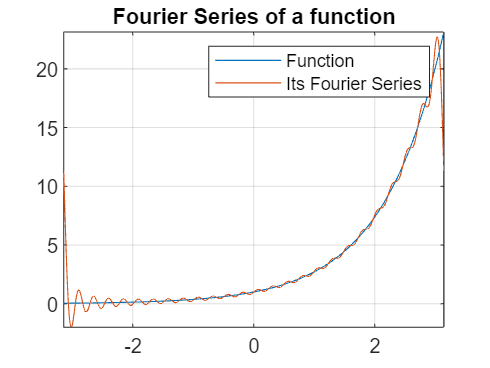


fplot(x,y,I)
grid on;
hold on;
fplot(x,F,I)
title('Fourier Series of a function')
legend('Function', 'Its Fourier Series')
hold off